Channel simulation

maxValue = 0.6;
minValue = -maxValue;
multi_path_num = 5;
randomNumbers_real = minValue + (maxValue - minValue) * rand(1, multi_path_num);
randomNumbers_imag = minValue + (maxValue - minValue) * rand(1, multi_path_num);

mpChan = [randomNumbers_real'+i.*randomNumbers_imag']  % multipath channel

mpChan =    0.3821 - 0.2249i
   0.3042 + 0.2213i
  -0.1271 + 0.1586i
  -0.1983 + 0.1122i
   0.0905 - 0.3576i


%plot(mpChan,"*")

SNR = 22   % dB, signal-to-noise ratio of AWGN

SNR = 22

initialization

nullIdx = [];
numCarr = 1024;
cycPre = 64;
modOrder = 16;  % for 4-QAM
% pilot_len = 8;
bitsPerSymbol = log2(modOrder)

bitsPerSymbol = 4


GB_len = numCarr/16;
left_gb = 1:GB_len

left_gb =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


right_gb = (numCarr-GB_len+1):numCarr

right_gb =          961         962         963         964         965         966         967         968         969         970         971         972         973         974         975         976         977         978         979         980         981         982         983         984         985         986         987         988         989         990         991         992         993         994         995         996         997         998         999        1000        1001        1002        1003        1004        1005        1006        1007        1008        1009        1010


if mod(numCarr,2) == 0
    mid_guard = (numCarr/2)+1
else
    mid_guard = (numCarr+1)/2
end

mid_guard = 513


nullIdx = [left_gb, mid_guard, right_gb]'

nullIdx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10



read_pilot = load('D:\Bristol\23-24\Project\Hardware\Simpler\Tx1\My_Pilot.mat','My_Pilot_Bits','my_QAM_pilot','My_Pilot')

read_pilot = 包含以下字段的 struct :
    My_Pilot_Bits: [3580×1 double]
     my_QAM_pilot: [895×1 double]
         My_Pilot: [1088×1 double]


pilot = read_pilot.My_Pilot

pilot =    0.0557 + 0.0353i
   0.0380 + 0.0084i
  -0.0010 + 0.0212i
   0.0548 + 0.0071i
  -0.0054 - 0.0052i
  -0.0213 + 0.0177i
  -0.0086 + 0.0075i
  -0.0193 + 0.0054i
   0.0142 - 0.0098i
  -0.0606 - 0.0078i


my_QAM_pilot = read_pilot.my_QAM_pilot

my_QAM_pilot =    0.9487 + 0.3162i
  -0.3162 - 0.9487i
   0.9487 + 0.9487i
   0.3162 - 0.9487i
   0.9487 + 0.3162i
  -0.9487 - 0.3162i
  -0.3162 - 0.3162i
   0.9487 - 0.9487i
  -0.3162 + 0.9487i
  -0.9487 + 0.3162i


My_Pilot_Bits = read_pilot.My_Pilot_Bits

My_Pilot_Bits =      1
     0
     0
     1
     0
     1
     1
     0
     1
     0



% %generate pilot
% my_pilot = dec2bin(2^(pilot_len*bitsPerSymbol -1) + pilot_len*cycPre -1)
% pilot = split(my_pilot,'')
% pilot = str2double(pilot(2:end-1))
% % pilot = zeros(pilot_len*2,1);
% pilot = [pilot;pilot];
% pilot(pilot_len-1) = 1
% pilot(pilot_len + 15) = 1

% %set pilot location
% intervial = round((numCarr - length(nullIdx))/(2*pilot_len))
% pilot_place = 1:intervial:1+intervial*(2*pilot_len-2)
% pilot_place = [pilot_place';numCarr - length(nullIdx)]
% pilotIdx = pilot_place
% 
% %set pilot bits location
% pilot_place = sort([bitsPerSymbol.*pilot_place;bitsPerSymbol.*pilot_place-1])
% bit_place = (1:(numCarr - length(nullIdx))*bitsPerSymbol)'
% bit_place(pilot_place) = []

numDataCarrs = numCarr-length(nullIdx)

numDataCarrs = 895

pilotIdx= 1:numDataCarrs

pilotIdx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



read_bit = load('D:\Bristol\23-24\Project\Hardware\Simpler\Tx1\My_data.mat','My_data')

read_bit = 包含以下字段的 struct :
    My_data: [3580×1 double]


test = read_bit.My_data

test =      1
     1
     1
     1
     0
     1
     1
     0
     0
     1



% test(pilot_place) = pilot
% test = zeros(numDataCarrs*bitsPerSymbol,1)
% size(test)
% test(125) = 1

% raw_bits = textread('D:\Bristol\23-24\Project\Hardware\Simpler\Tx1\tx_bits.txt', '%d', 'delimiter', ' ');
% barker = [-1; -1; -1; 1; 1; -1; 1; 1];

QAM Modulation

my_QAM = qammod(test,modOrder,"InputType","bit","UnitAveragePower",true)

my_QAM =    0.3162 - 0.3162i
  -0.3162 - 0.9487i
  -0.3162 - 0.9487i
  -0.3162 + 0.3162i
  -0.9487 + 0.9487i
   0.3162 - 0.9487i
  -0.9487 + 0.9487i
   0.3162 + 0.9487i
  -0.9487 - 0.9487i
  -0.3162 + 0.9487i



%scatterplot(my_QAM)
my_test_QAM = my_QAM(pilotIdx)

my_test_QAM =    0.3162 - 0.3162i
  -0.3162 - 0.9487i
  -0.3162 - 0.9487i
  -0.3162 + 0.3162i
  -0.9487 + 0.9487i
   0.3162 - 0.9487i
  -0.9487 + 0.9487i
   0.3162 + 0.9487i
  -0.9487 - 0.9487i
  -0.3162 + 0.9487i


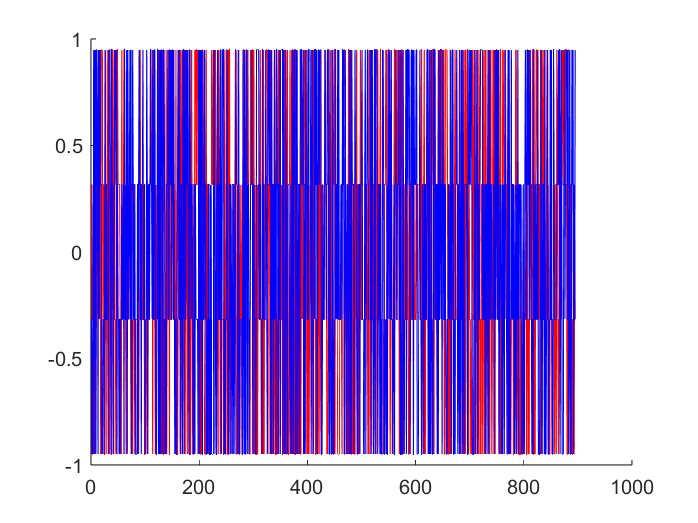


figure()
hold on
plot(real(my_QAM),'r')
plot(imag(my_QAM),'b')
hold off


% pilots = qammod(pilot,modOrder,"InputType","bit","UnitAveragePower",true)
% 
% nnz(my_test_QAM ~= pilots)

read_header = load('D:\Bristol\23-24\Project\Hardware\Simpler\Tx1\complexArray.mat',"my_ofdm");
my_header = read_header.my_ofdm

my_header =   -0.0413 - 0.0906i
  -0.0983 - 0.0780i
   0.1643 + 0.4204i
   0.1018 + 0.2345i
  -0.2396 + 0.0058i
  -0.3505 - 0.1614i
   0.3652 + 0.0042i
   0.4995 - 0.2753i
  -0.2410 - 0.5883i
  -0.5125 + 0.2220i



% read_tail = load('my_tail.mat','my_tail');
% my_tail = read_tail.my_tail;

OFDM Modulation

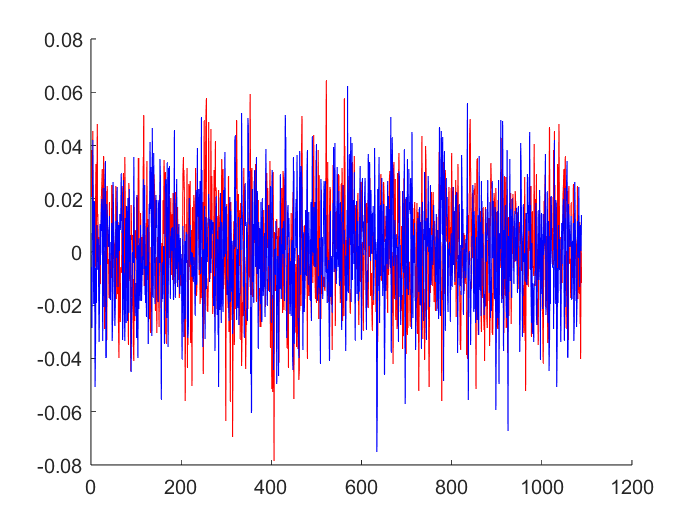

my_ofdm = ofdmmod(my_QAM,numCarr,cycPre,nullIdx);

figure()
hold on
plot(real(my_ofdm),'r')
plot(imag(my_ofdm),'b')
hold off


size_my_ofdm = size(my_ofdm)

size_my_ofdm =         1088           1


my_ofdm = [pilot;my_ofdm]

my_ofdm =    0.0557 + 0.0353i
   0.0380 + 0.0084i
  -0.0010 + 0.0212i
   0.0548 + 0.0071i
  -0.0054 - 0.0052i
  -0.0213 + 0.0177i
  -0.0086 + 0.0075i
  -0.0193 + 0.0054i
   0.0142 - 0.0098i
  -0.0606 - 0.0078i


Amplify the Signal

my_real_tx_gain =1 / max(real(my_ofdm))

my_real_tx_gain = 15.2293

my_imag_tx_gain =1 / max(imag(my_ofdm))

my_imag_tx_gain = 16.1159

my_tx_gain = min(my_real_tx_gain,my_imag_tx_gain)

my_tx_gain = 15.2293


my_ofdm = [my_ofdm].*my_tx_gain/2;  % to make it bit smaller. to make a larger SNR, remove "/10"

tx_data = [my_header;my_ofdm;zeros(numCarr+cycPre,1)];

% tx_data = [tx_data;zeros(numCarr+cycPre,1)];
size(tx_data)

ans =         4352           1


Apply Multi-channel and AWGN

tx_data = tx_data 

tx_data =   -0.0413 - 0.0906i
  -0.0983 - 0.0780i
   0.1643 + 0.4204i
   0.1018 + 0.2345i
  -0.2396 + 0.0058i
  -0.3505 - 0.1614i
   0.3652 + 0.0042i
   0.4995 - 0.2753i
  -0.2410 - 0.5883i
  -0.5125 + 0.2220i


mpChanOut = filter(mpChan,1,tx_data); %apply mutipat

%chanOut = mpChanOut
Rx_sig = awgn(mpChanOut,SNR,"measured") %apply AWGN

Rx_sig =   -0.0373 - 0.0192i
  -0.0582 - 0.0535i
   0.1629 + 0.0872i
   0.1139 + 0.2426i
  -0.2052 + 0.1329i
  -0.4252 - 0.0718i
   0.2145 - 0.2974i
   0.4621 - 0.2214i
   0.0370 + 0.0076i
  -0.2734 + 0.2327i


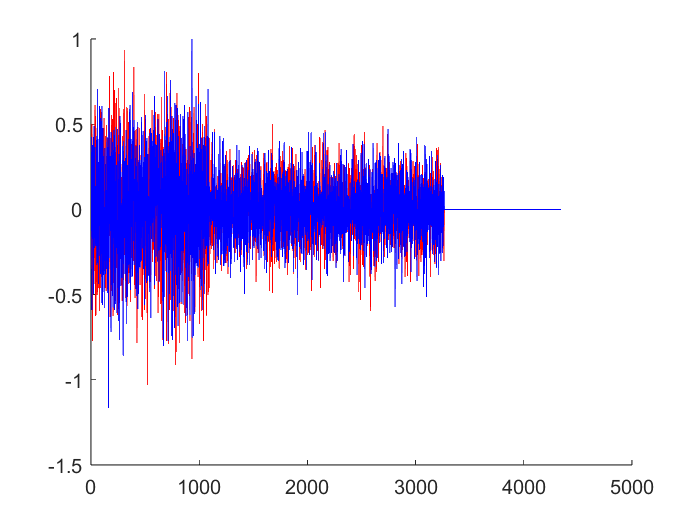

% Rx_sig = mpChanOut

figure()
hold on
plot(real(tx_data),'r')
plot(imag(tx_data),'b')
hold off

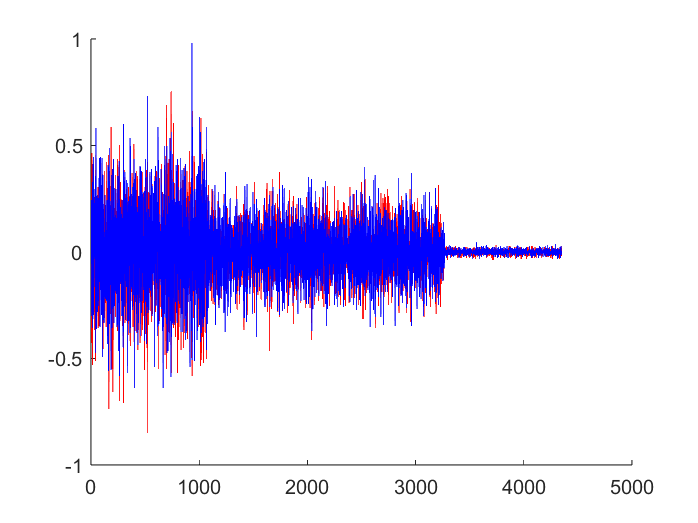


figure()
hold on
plot(real(Rx_sig),'r')
plot(imag(Rx_sig),'b')
hold off

% scatterplot(tx_data)
tx_data = Rx_sig;

## RX Simulation

find header / tail

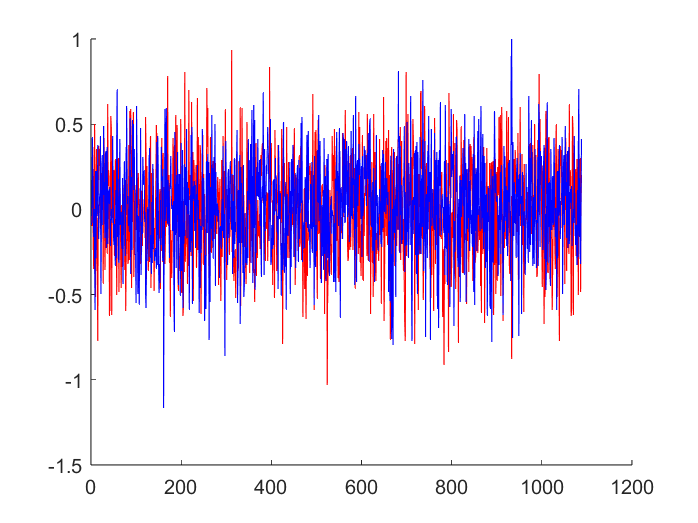

read_header = load('D:\Bristol\23-24\Project\Hardware\Simpler\Tx1\complexArray.mat',"my_ofdm");
my_header = read_header.my_ofdm;

figure()
hold on
plot(real(my_header),'r')
plot(imag(my_header),'b')
hold off


head_detec = comm.PreambleDetector('Input','Symbol','Preamble',my_header,'Threshold',2,'Detections','All')

head_detec =   comm.PreambleDetector - 属性:

         Input: 'Symbol'
      Preamble: [1088×1 double]
     Threshold: 2
    Detections: 'All'


[head_idx,head_detmet] = head_detec(tx_data)

head_idx =     64
    65
    66
    67
    68
    80
    81
    82
    83
    84


head_detmet =     0.0194
    0.0396
    0.1009
    0.1744
    0.1187
    0.2866
    0.1745
    0.3388
    0.0580
    0.2566


[head_maxCorr, head_maxIndex] = max(head_detmet)

head_maxCorr = 84.2727

head_maxIndex = 1088


% head_maxIndex = 144

% tail_detec = comm.PreambleDetector('Input','Symbol','Preamble',my_tail,'Threshold',2,'Detections','All')
% [tail_idx,tail_detmet] = tail_detec(tx_data)
% [tail_maxCorr, tail_maxIndex] = max(tail_detmet)

% if tail_maxCorr > head_maxCorr
%     from_tail = tail_maxIndex-numCarr-cycPre-length(my_tail)+1:tail_maxIndex-length(my_tail)
%     ofdm_received = tx_data(tail_maxIndex-numCarr-cycPre-length(my_tail)+1:tail_maxIndex-length(my_tail))
% else
    from_head = head_maxIndex+1:head_maxIndex+numCarr+cycPre+length(pilot)

from_head =         1089        1090        1091        1092        1093        1094        1095        1096        1097        1098        1099        1100        1101        1102        1103        1104        1105        1106        1107        1108        1109        1110        1111        1112        1113        1114        1115        1116        1117        1118        1119        1120        1121        1122        1123        1124        1125        1126        1127        1128        1129        1130        1131        1132        1133        1134        1135        1136        1137        1138


    ofdm_received = tx_data(from_head)

ofdm_received =    0.2338 + 0.0246i
  -0.0667 + 0.2397i
  -0.0358 + 0.1213i
   0.1492 - 0.0358i
   0.1254 - 0.0454i
  -0.0771 + 0.0205i
  -0.1094 + 0.0979i
  -0.0198 - 0.1210i
  -0.0319 - 0.1456i
  -0.1148 + 0.1077i


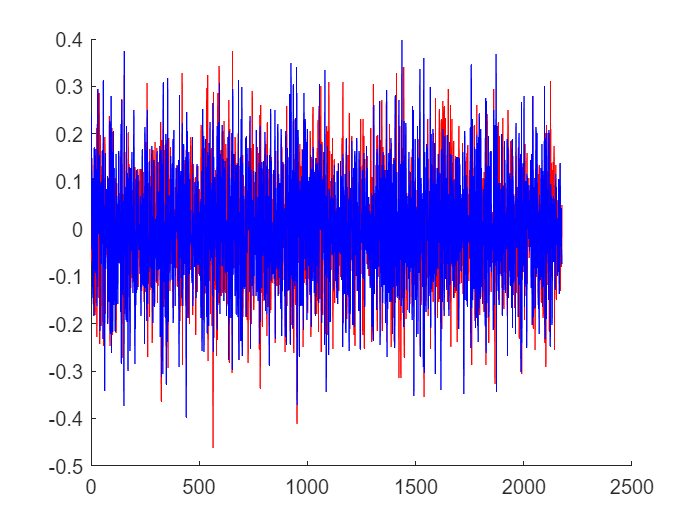

% end

% ofdm_received = tx_data(maxIndex+1:maxIndex+numCarr+cycPre)
% size(ofdm_received)

figure()
hold on
plot(real(ofdm_received),'r')
plot(imag(ofdm_received),'b')
hold off

OFDM Demodulation

pilot_received = ofdm_received(1 : numCarr+cycPre);
data_received = ofdm_received(numCarr+cycPre+1 : end);
rxPilots = ofdmdemod(pilot_received,numCarr,cycPre,cycPre,nullIdx)

rxPilots =   -1.9438 - 4.0399i
  -2.0818 + 3.8224i
   0.2164 - 5.7189i
  -3.0897 + 1.3176i
  -1.9834 - 3.8099i
   1.4390 + 3.7585i
   0.4598 + 1.7175i
  -5.1834 + 0.7384i
   3.4476 - 2.1349i
   3.8803 + 1.5234i


my_received_data = ofdmdemod(data_received,numCarr,cycPre,cycPre,nullIdx)

my_received_data =   -1.8958 + 0.0268i
  -2.0434 + 3.7870i
  -1.2476 + 3.4859i
   1.9295 - 0.2984i
   5.3661 + 0.7195i
  -3.5149 + 1.5832i
   5.5360 - 0.3073i
   1.3297 - 3.0961i
   0.0538 + 5.2863i
   2.9632 - 2.1855i


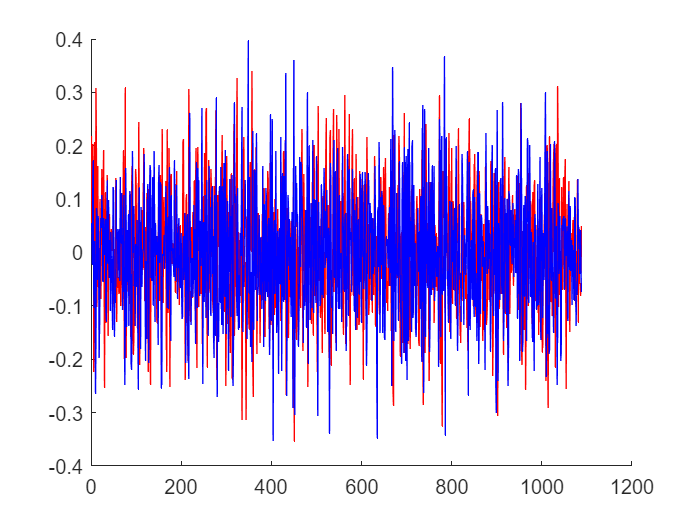


% ofdm_deout = [ofdm_deout(:,1);ofdm_deout(:,2)]

figure()
hold on
plot(real(data_received),'r')
plot(imag(data_received),'b')
hold off

% my_received_data = ofdmdemod(data_received,numCarr,cycPre,cycPre,nullIdx)
% test_demod_data = qamdemod(my_received_data,4,"OutputType","bit","UnitAveragePower",true)
% nnz(test~=qamDemodOut)

% figure()
% hold on
% plot(real(test_demod_data),'r')
% plot(imag(test_demod_data),'b')
% hold off

Channel Estimation

estimatedChannelResponse = rxPilots ./ my_QAM_pilot;

% test pilot estimation
pilot_estimation = rxPilots ./ estimatedChannelResponse

pilot_estimation =    0.9487 + 0.3162i
  -0.3162 - 0.9487i
   0.9487 + 0.9487i
   0.3162 - 0.9487i
   0.9487 + 0.3162i
  -0.9487 - 0.3162i
  -0.3162 - 0.3162i
   0.9487 - 0.9487i
  -0.3162 + 0.9487i
  -0.9487 + 0.3162i


test_pilot = qamdemod(pilot_estimation,modOrder,"OutputType","bit","UnitAveragePower",true)

test_pilot =      1
     0
     0
     1
     0
     1
     1
     0
     1
     0


nnz(test_pilot~=My_Pilot_Bits)

ans = 0

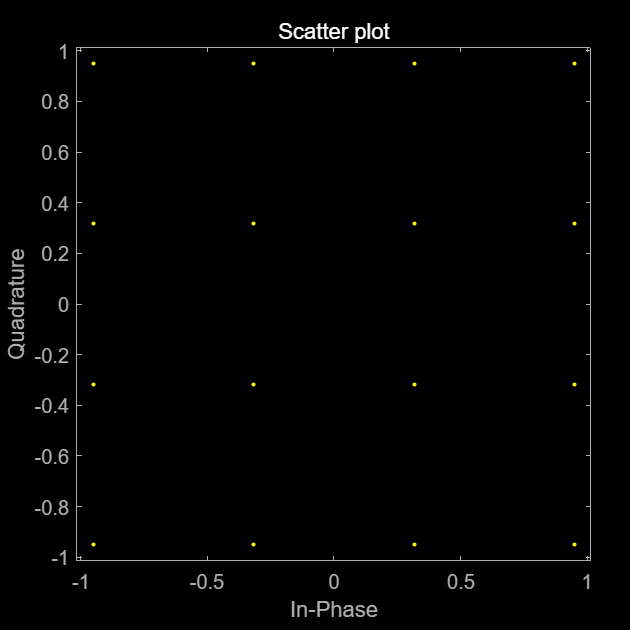

scatterplot(pilot_estimation)


equalizedSignal = my_received_data ./ estimatedChannelResponse

equalizedSignal =    0.2901 - 0.3077i
  -0.3163 - 0.9367i
  -0.4005 - 0.7701i
  -0.3144 + 0.4889i
  -1.0142 + 0.7485i
   0.2502 - 0.9246i
  -1.1671 + 0.7634i
   0.2038 + 0.8391i
  -0.8446 - 0.9931i
  -0.2095 + 0.8581i


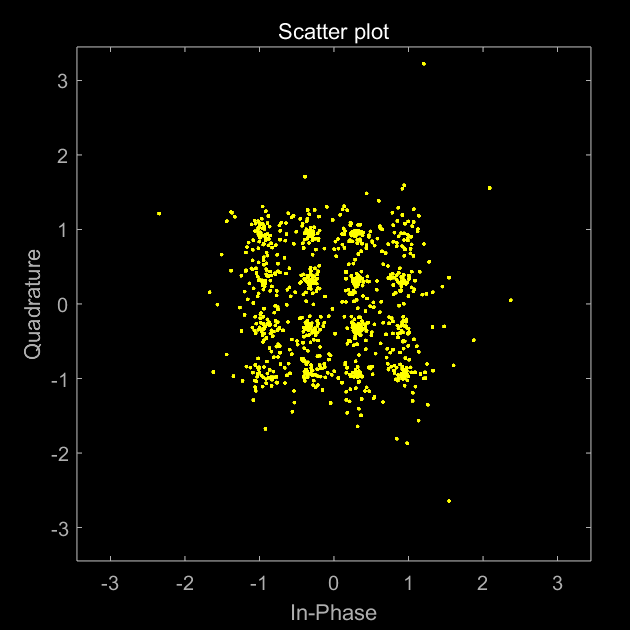

scatterplot(equalizedSignal)


qamDemodOut = qamdemod(equalizedSignal,modOrder,"OutputType","bit","UnitAveragePower",true)

qamDemodOut =      1
     1
     1
     1
     0
     1
     1
     0
     0
     1


nnz(test~=qamDemodOut)

ans = 132


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Channel Estimation
% rxPilots = ofdm_deout(pilotIdx)
silent_period = Rx_sig(head_maxIndex+(numCarr+cycPre)*2+1 : round(head_maxIndex+(numCarr+cycPre)*2.9))

silent_period =   -0.0036 + 0.0692i
  -0.0397 + 0.0860i
  -0.0006 - 0.0474i
   0.0280 + 0.0190i
  -0.0200 - 0.0201i
   0.0120 - 0.0024i
   0.0038 - 0.0107i
   0.0113 - 0.0150i
  -0.0147 + 0.0150i
  -0.0123 - 0.0048i


sigma_n_squared = var(silent_period) 

sigma_n_squared = 2.7226e-04


channel_response_estimate = rxPilots ./ my_QAM_pilot;

sigma_H_squared = var(abs(channel_response_estimate))

sigma_H_squared = 9.7016


H_est_MMSE = zeros(numCarr-length(nullIdx),1);

Y_over_X = rxPilots ./ my_QAM_pilot;
show_MMSE = (sigma_H_squared / (sigma_H_squared + sigma_n_squared));
% MMSE估计
H_est_MMSE = (sigma_H_squared / (sigma_H_squared + sigma_n_squared)) .* Y_over_X;

% H_est_full_MMSE = interp1(pilotIdx, H_est_MMSE, 1:(numCarr-length(nullIdx)), 'linear', 'extrap');

equalizedSignal_MMSE = my_received_data ./ H_est_MMSE;
qamDemodOut_MMSE = qamdemod(equalizedSignal_MMSE,modOrder,"OutputType","bit","UnitAveragePower",true)

qamDemodOut_MMSE =      1
     1
     1
     1
     0
     1
     1
     0
     0
     1


nnz(test~=qamDemodOut)

ans = 132

nnz(test~=qamDemodOut_MMSE)

ans = 132

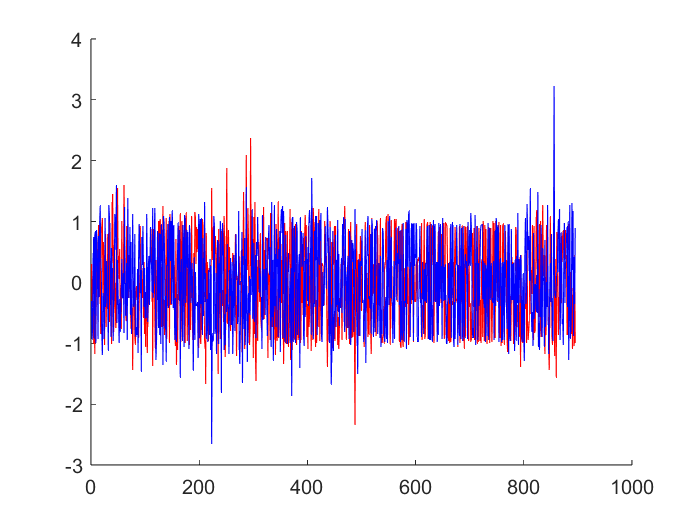

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure()
hold on
plot(real(equalizedSignal),'r')
plot(imag(equalizedSignal),'b')
hold off



figure()
hold on
plot(real(equalizedSignal),'r')
plot(imag(equalizedSignal),'b')
hold off

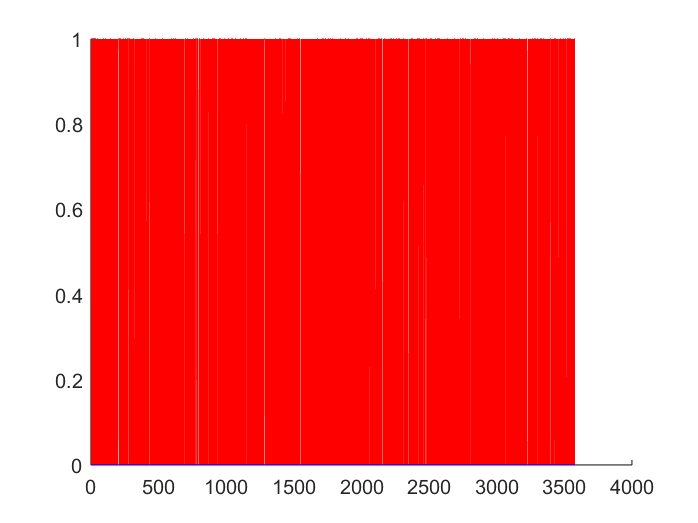


figure()
hold on
plot(real(qamDemodOut),'r')
plot(imag(qamDemodOut),'b')
hold off


figure()
hold on
plot(real(qamDemodOut_MMSE),'r')
plot(imag(qamDemodOut_MMSE),'b')
hold off